# A: Training Data Visualization

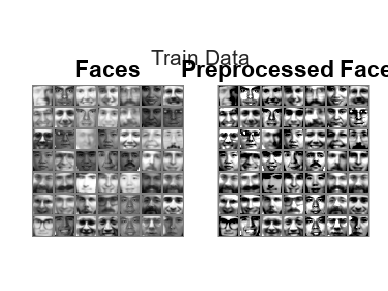

faceData = importdata('face.txt');
numFaces = 49;
selectedIndices = randsample(size(faceData, 2), numFaces);
normalizedFaces = normalize_faces(faceData);

figure('Color', 'w');
tiledlayout(1, 2, 'TileSpacing', 'Compact', 'Padding', 'Compact');
sgtitle('Train Data');
nexttile;
imshow(uint8(compact_canvas(faceData(:, selectedIndices))));
title('Faces', 'FontSize', 14);
axis off;

nexttile;
imshow(compact_canvas(normalizedFaces(:, selectedIndices)));
title('Preprocessed Faces', 'FontSize', 14);
axis off;
colormap(gray);

% Save the training data figure as JPEG
saveas(gcf, 'TrainData.jpeg');

## B: NMF and Basis Elements

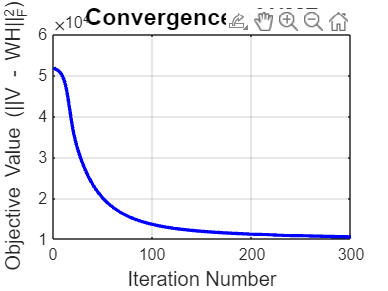

max_iter = 300;
[W, H, objective_val_history] = nmf(normalizedFaces, numFaces, max_iter);

figure('Name', 'NMF Convergence', 'Color', 'w');
plot(1:max_iter, objective_val_history, 'LineWidth', 2, 'Color', 'b');
xlabel('Iteration Number', 'FontSize', 12);
ylabel('Objective Value (||V - WH||_F^2)', 'FontSize', 12);
title('Convergence of NMF', 'FontSize', 14);
grid on;
saveas(gcf, 'NMF_Convergence.jpeg');

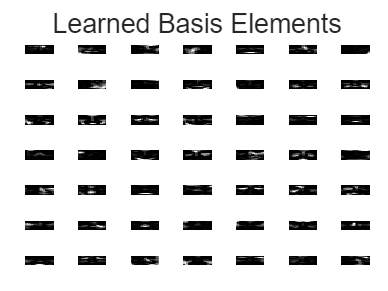


imgSize = sqrt(size(W, 1));
if mod(imgSize, 1) == 0
    numBasis = size(W, 2);
    numRows = ceil(sqrt(numBasis));
    numCols = ceil(numBasis / numRows);
    
    figure('Name', 'Learned Basis Elements', 'Color', 'w');
    tiledlayout(numRows, numCols, 'TileSpacing', 'Compact', 'Padding', 'Compact');
    for i = 1:numBasis
        nexttile;
        imagesc(reshape(W(:, i), imgSize, imgSize));
        axis off;
    end
    colormap(gray);
    sgtitle('Learned Basis Elements', 'FontSize', 16);
    saveas(gcf, 'Learned_BasisElements.jpeg');
else
    figure('Name', 'W Matrix', 'Color', 'w');
    imshow(compact_canvas(W));
    title('W Matrix', 'FontSize', 14);
    colormap(gray);
    saveas(gcf, 'W_Matrix.jpeg');
end

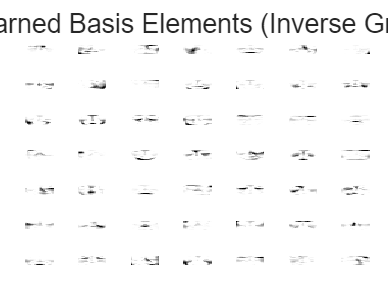


if mod(imgSize, 1) == 0
    numBasis = size(W, 2);
    numRows = ceil(sqrt(numBasis));
    numCols = ceil(numBasis / numRows);
    
    figure('Name', 'Learned Basis Elements (Inverse Gray)', 'Color', 'w');
    tiledlayout(numRows, numCols, 'TileSpacing', 'Compact', 'Padding', 'Compact');
    for i = 1:numBasis
        nexttile;
        imagesc(reshape(W(:, i), imgSize, imgSize));
        axis off;
    end
    colormap(flipud(gray));
    sgtitle('Learned Basis Elements (Inverse Gray)', 'FontSize', 16);
    saveas(gcf, 'Learned_BasisElements_Inverse.jpeg');
else
    figure('Name', 'W Matrix (Inverse Gray)', 'Color', 'w');
    imshow(compact_canvas(W));
    title('W Matrix', 'FontSize', 14);
    colormap(flipud(gray));
    saveas(gcf, 'W_Matrix_Inverse.jpeg');
end

## D: Test Data Reconstruction

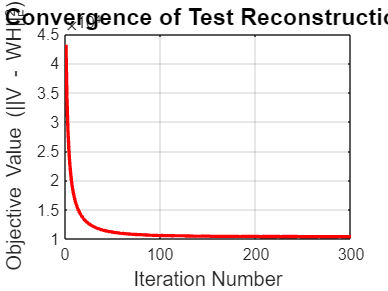

faceData_test = importdata('face_test.txt');
selected = randsample(size(faceData_test, 2), numFaces);
testV_normalized = normalize_faces(faceData_test);
[objective_val_history, H] = test_faces(W, testV_normalized);

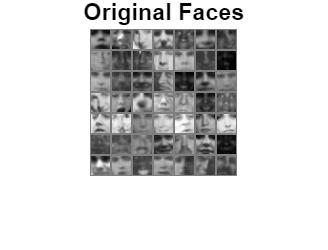

reconstrate = W * H;
mse_val = mse(testV_normalized - reconstrate);

figure('Name', 'Original Faces', 'Color', 'w');
imshow(uint8(compact_canvas(faceData_test(:, selected))));
title('Original Faces', 'FontSize', 14);
axis off;
saveas(gcf, 'OriginalFaces_partD.jpeg');

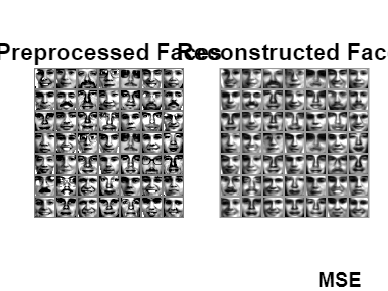


figure('Name', 'Preprocessed and Reconstructed Faces', 'Color', 'w');
tiledlayout(1, 2, 'TileSpacing', 'Compact', 'Padding', 'Compact');

nexttile;
imshow(compact_canvas(testV_normalized(:, selected)));
title('Preprocessed Faces', 'FontSize', 14);
axis off;

nexttile;
imshow(compact_canvas(reconstrate(:, selected)));
title('Reconstructed Faces', 'FontSize', 14);
axis off;

% Add the MSE annotation to the second figure
annotation('textbox', [0.80, 0.05, 0.15, 0.05], 'String', sprintf('MSE = %.4f', mse_val), ...
    'EdgeColor', 'none', 'FontSize', 12, 'FontWeight', 'bold', 'HorizontalAlignment', 'center');

saveas(gcf, 'Preprocessed_Reconstructed.jpeg');